# Problem 1

max = 50;
N = 10;
x_max = max;
x_step = 2*max/N;
y_max = max;
y_step = 2*max/N;
[y0_x, y0_y] = meshgrid(-x_max:x_step:x_max, -y_max:y_step:y_max);
w = min(x_step,y_step)/5;

xsize = size(y0_x);
ysize = size(y0_y);
% zsize = size(y0_z);
y0 = [reshape(y0_x, 1,xsize(1)*xsize(2)); %*xsize(3)); 
      reshape(y0_y, 1,ysize(1)*ysize(2))]; %*ysize(3))];
%       reshape(y0_z, 1,zsize(1)*zsize(2)*zsize(3))];

tspan = [0 50];

clf;
figure(1)
hold 

Current plot held


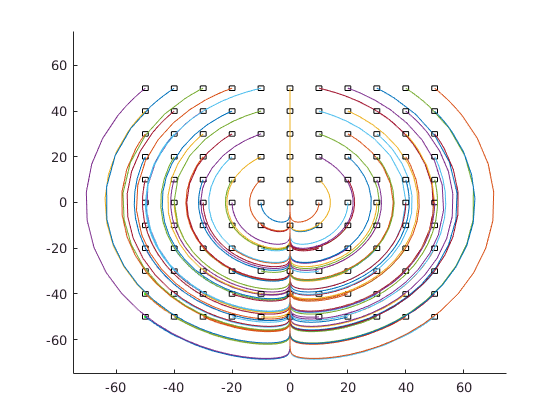

plot(y0(:,1), y0(:,2), '.g')
for i=1:length(y0)
   y_init = y0(:,i);
   [t, y] = ode45(@my_ode,tspan,y_init);
%    plot3(y(:,1), y(:,2)), y(:,3));
    rectangle('Position',[y(1,1)-w/2,y(1,2)-w/2,w,w])
    plot(y(:,1), y(:,2))
end
axis([-max max -max max]*1.5)


% ODE function

function [yout] = my_ode(t, yin)
  mu = -0.0;
  x1 = yin(1);
  x2 = yin(2);
  
  x1dot = x1*x2;
  x2dot = -x1^2 - x2;
%   x2dot = -x1 + mu*x2;


  yout = [x1dot; x2dot];

end